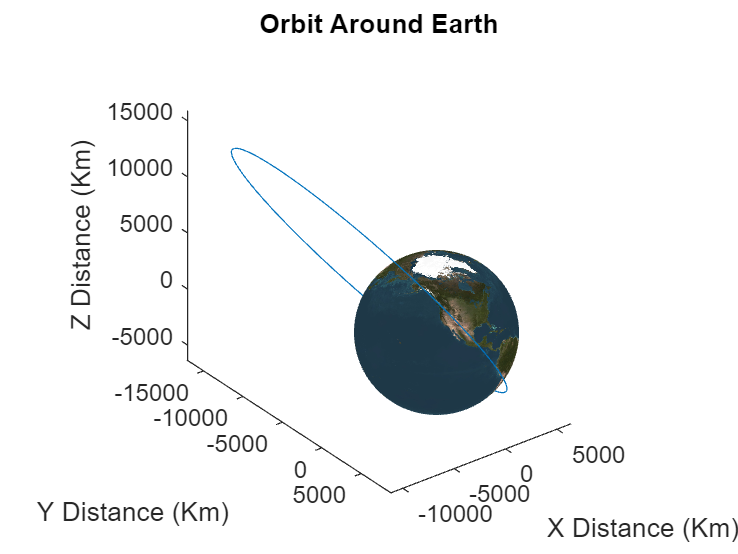

% Add functions folder to path
addpath("functions\");

% Make 3D Sphere of Earth to scale

plotearth

% Input orbit data from inputorbit function
[ap, pe, offset_angle, inc_angle] = inputorbit;

% Input orbit name to save to files
orbit_name = input("Please Input Orbit Name: ","s");

% Calculate orbital data based on the calculateorbit function
[x, y, z] = calculateorbit(ap, pe, offset_angle, inc_angle, orbit_name);


% Plot orbit in 3d 
plot3(x,y,z)

% Save Orbit File as PNG in output folder
file_name = "output\" + orbit_name + "_3D_orbit.png";

saveas(gcf, file_name)

% 3D Plot Labels and Title
title("Orbit Around Earth")
xlabel("X Distance (Km)")
ylabel("Y Distance (Km)")
zlabel("Z Distance (Km)")
hold off

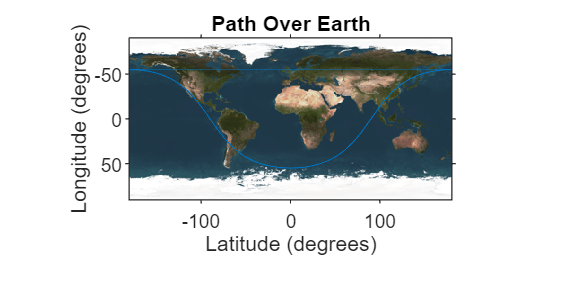


% Plot the orbit in 2d with longitude and latitude
plotorbit2d(x,y,z, orbit_name)